% n = 5; % Size of the matrix
% a = rand(n, 1); % Main diagonal
% b = rand(n-1, 1); % First upper and lower diagonals
% c = rand(n-2, 1); % Second upper and lower diagonals
% d = rand(n-3, 1); % Third upper and lower diagonals
% 
% % Create the pentadiagonal matrix
% A_k = diag(a) + diag(b, 1) + diag(b, -1) + diag(c, 2) + diag(c, -2) + diag(d, 3) + diag(d, -3);
% 
% % Display the matrix
% disp(A_k);
% spy(A_k);
% title("Pentadiagonal matrix, A_k")

% n = 5; % Size of the matrix
% diagonal = rand(n, 1); % Random values for the main diagonal
% subDiagonal = rand(n-1, 1); % Random values for the sub-diagonal
% superDiagonal = rand(n-1, 1); % Random values for the super-diagonal
% 
% % Create the tridiagonal matrix
% A_0 = diag(diagonal) + diag(subDiagonal, -1) + diag(superDiagonal, 1);
% 
% disp(A_0); % Display the matrix
% spy(A_0);
% title("Tridiagonal matrix, A_0")

% % Inverse of A_k
% inv_A_k = inv(A_k);
% disp(inv_A_k);
% spy(inv_A_k);
% title("A_k inverse - transitive closure")

% Compute Exact Map
% N = inv_A_k * A_0;
% disp(N);
% spy(N);
% title("Exact Map - 1")

% Set the size of the matrix
rows = 10;
cols = 10;

% Set the density of non-zero elements (adjust as needed)
density = 0.4;

% Generate the random sparse matrix
M_k = sprand(rows, cols, density);

% Set the diagonal elements to non-zero values
diagonal_values = rand(rows, 1);
M_k = M_k + spdiags(diagonal_values, 0, rows, cols);

% Display the sparse matrix
disp(M_k);

   (1,1)       0.6541
   (2,2)       0.6892
   (4,2)       0.3804
   (5,2)       0.0759
   (7,2)       0.7792
   (9,2)       0.3371
   (1,3)       0.3517
   (2,3)       0.5497
   (3,3)       0.7482
   (4,3)       0.5678
  (10,3)       0.5285
   (4,4)       0.4505
   (9,4)       0.1622
  (10,4)       0.1656
   (1,5)       0.8308
   (2,5)       0.9172
   (3,5)       0.7572
   (5,5)       0.0838
   (9,5)       0.7943
   (6,6)       0.2290
   (8,6)       0.5688
   (9,6)       0.3112
   (6,7)       0.5308
   (7,7)       0.9133
  (10,7)       0.6020
   (2,8)       0.2858
   (7,8)       0.9340
   (8,8)       0.1524
  (10,8)       0.2630
   (3,9)       0.7537
   (7,9)       0.1299
   (8,9)       0.4694
   (9,9)       0.8258
   (1,10)      0.5853
   (5,10)      0.0540
   (8,10)      0.0119
  (10,10)      0.5383



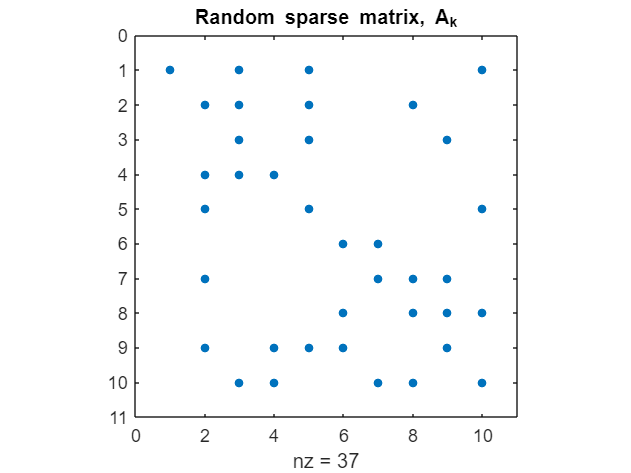

spy(M_k);
title("Random sparse matrix, A_k")

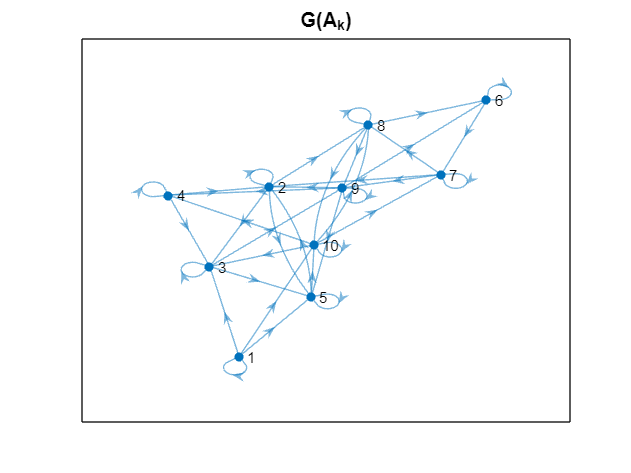

plot(digraph(M_k));
title("G(A_k)")

% Inverse of M_k
inv_M_k = inv(M_k);
disp(inv_M_k);

   (1,1)       1.5289
   (1,2)      -1.3403
   (2,2)      -1.2295
   (3,2)      -0.0398
   (4,2)       1.0883
   (5,2)       1.5431
   (6,2)       0.8352
   (7,2)      -0.3603
   (8,2)       1.5881
   (9,2)      -1.5107
  (10,2)      -0.6687
   (1,3)       0.7914
   (2,3)       1.2217
   (3,3)       1.1345
   (4,3)      -2.4615
   (5,3)      -1.1303
   (6,3)      -0.7013
   (7,3)       0.3025
   (8,3)      -1.5008
   (9,3)       1.3361
  (10,3)       0.0384
   (1,4)       1.0746
   (2,4)       1.2115
   (3,4)       0.6231
   (4,4)       0.4112
   (5,4)      -0.9549
   (6,4)       0.0061
   (7,4)      -0.0026
   (8,4)      -1.0555
   (9,4)       0.3408
  (10,4)      -0.2198
   (1,5)       2.2811
   (2,5)      17.3514
   (3,5)       3.2788
   (4,5)     -18.7842
   (5,5)     -10.0003
   (6,5)      -1.5062
   (7,5)       0.6497
   (8,5)     -16.0548
   (9,5)       6.7917
  (10,5)       9.6767
   (1,6)       0.6181
   (2,6)       0.6584
   (3,6)       0.3715
   (4,6)      -1.0242
   (5,6)  

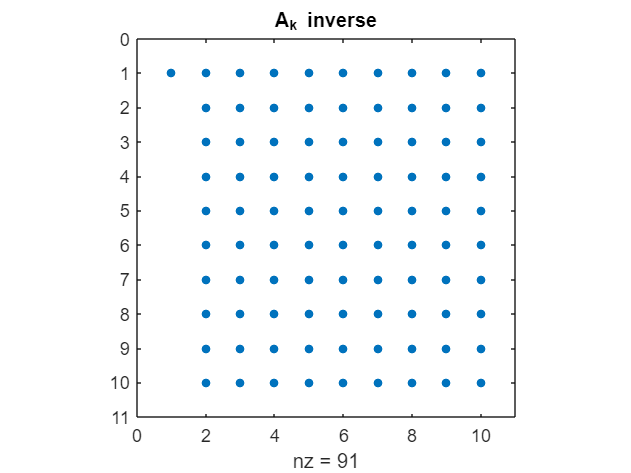

spy(inv_M_k);
title("A_k inverse")

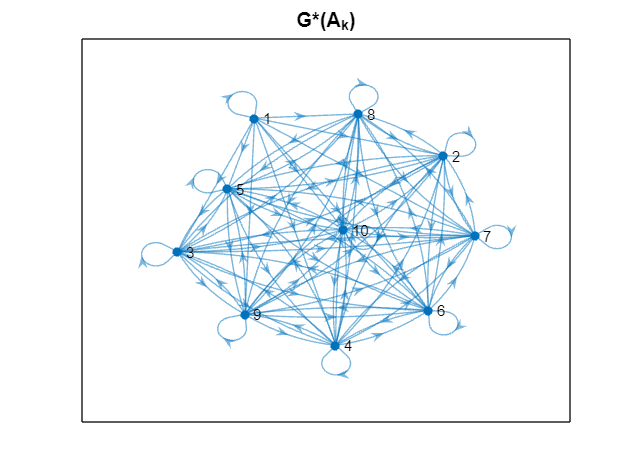

plot(digraph(inv_M_k));
title("G*(A_k)")

% Extract the diagonal elements as a column vector
%diagonal_vector = spdiags(M_k, 0);

% Convert the diagonal vector to a diagonal matrix
%diagonal_matrix = spdiags(diagonal_vector, 0, size(M_k, 1), size(M_k, 2));

% Display the diagonal matrix
%disp(diagonal_matrix);
%spy(diagonal_matrix);

% Extract the upper triangular matrix
upper_triangular_matrix = triu(M_k);

% Display the upper triangular matrix
disp(upper_triangular_matrix);

   (1,1)       0.6541
   (2,2)       0.6892
   (1,3)       0.3517
   (2,3)       0.5497
   (3,3)       0.7482
   (4,4)       0.4505
   (1,5)       0.8308
   (2,5)       0.9172
   (3,5)       0.7572
   (5,5)       0.0838
   (6,6)       0.2290
   (6,7)       0.5308
   (7,7)       0.9133
   (2,8)       0.2858
   (7,8)       0.9340
   (8,8)       0.1524
   (3,9)       0.7537
   (7,9)       0.1299
   (8,9)       0.4694
   (9,9)       0.8258
   (1,10)      0.5853
   (5,10)      0.0540
   (8,10)      0.0119
  (10,10)      0.5383



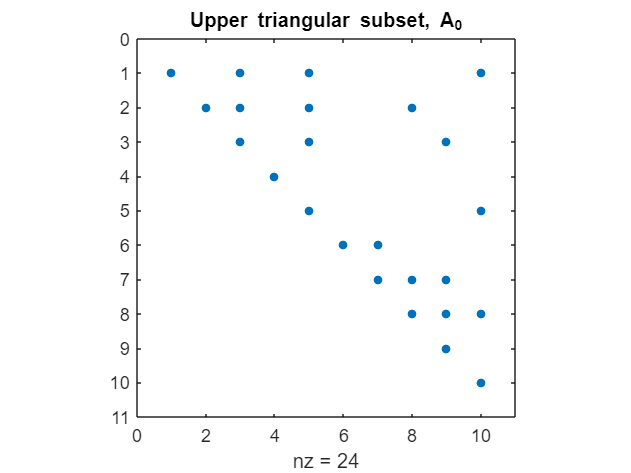

spy(upper_triangular_matrix);
title("Upper triangular subset, A_0")

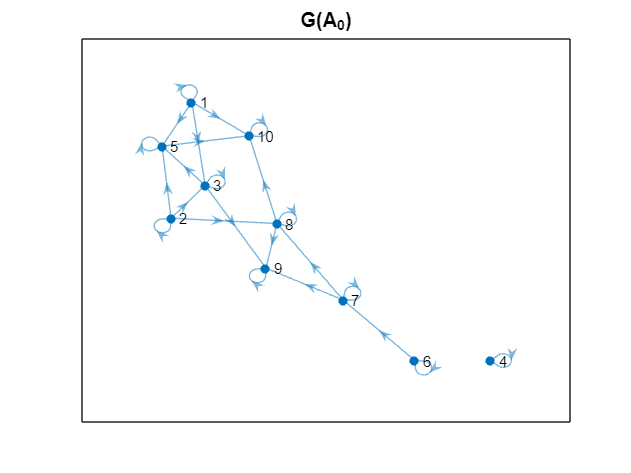

plot(digraph(upper_triangular_matrix));
title("G(A_0)")

% Compute Exact Map with diagonal A_0
%N = inv_M_k * diagonal_matrix;
%disp(N);
%spy(N);

% Compute Exact Map with Upper Triangular A_0
N = inv_M_k * upper_triangular_matrix;
disp(N);

   (1,1)       1.0000
   (1,2)      -0.9238
   (2,2)      -0.8474
   (3,2)      -0.0274
   (4,2)       0.7501
   (5,2)       1.0635
   (6,2)       0.5756
   (7,2)      -0.2483
   (8,2)       1.0946
   (9,2)      -1.0412
  (10,2)      -0.4609
   (1,3)       0.3929
   (2,3)       0.2381
   (3,3)       0.8269
   (4,3)      -1.2433
   (5,3)       0.0026
   (6,3)      -0.0655
   (7,3)       0.0283
   (8,3)      -0.2498
   (9,3)       0.1691
  (10,3)      -0.3389
   (1,4)       0.4841
   (2,4)       0.5458
   (3,4)       0.2807
   (4,4)       0.1853
   (5,4)      -0.4302
   (6,4)       0.0028
   (7,4)      -0.0012
   (8,4)      -0.4755
   (9,4)       0.1535
  (10,4)      -0.0990
   (1,5)       0.8314
   (2,5)       1.2518
   (3,5)       1.0974
   (4,5)      -2.4401
   (5,5)      -0.2788
   (6,5)       0.1088
   (7,5)      -0.0469
   (8,5)      -1.0255
   (9,5)       0.1954
  (10,5)       0.2268
   (1,6)       0.1415
   (2,6)       0.1508
   (3,6)       0.0851
   (4,6)      -0.2345
   (5,6)  

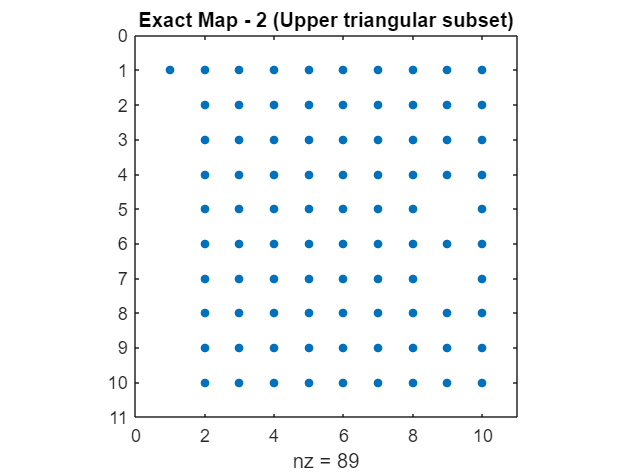

spy(N);
title("Exact Map - 2 (Upper triangular subset)")

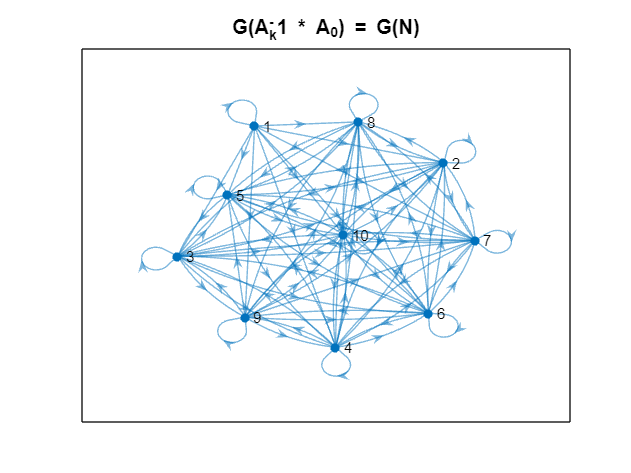

plot(digraph(N));
title("G(A_k^-1 * A_0) = G(N)")

% Compute SAM with Upper Triangular A_0
% Preprocess the sparsity pattern (here, we use patt(A_0))
[I,J] = find(upper_triangular_matrix);
findJ = sparse(I,J,1);
PP = logical(findJ);
PP2 = logical(sparse(double(PP)*double(PP))); % Taking powers of A_0 as apriori sparsity pattern for the map
nnzMM = nnz(PP2);
rowM = zeros(2*nnzMM,1);
colM = zeros(2*nnzMM,1);
valM = zeros(2*nnzMM,1);

% Compute SAM
for j = 1:cols
    % Initialize these later for efficiency...
    nz_M{j} = find(PP(:,j));
    nnz_M(j) = length(nz_M{j});
    nz_LS{j} = find(PP2(:,j));
    nnz_LS(j) = length(nz_LS{j});
end

max_col = max(nnz_M);
max_row = max(nnz_LS);
A_hat = zeros(max_row,max_col);
M_sam = zeros(max_row,1);
cntrM = 0;
for j = 1:cols
    A_hat(1:nnz_LS(j),1:nnz_M(j)) = M_k(nz_LS{j},nz_M{j});
    %[rC,cC] = size(A_hat(1:nnz_LS(j),1:nnz_M(j)));
    M_sam(1:nnz_M(j)) = A_hat(1:nnz_LS(j),1:nnz_M(j))\upper_triangular_matrix(nz_LS{j},j);
    rowM(cntrM+1:cntrM+nnz_M(j)) = nz_M{j};
    colM(cntrM+1:cntrM+nnz_M(j)) = j;
    valM(cntrM+1:cntrM+nnz_M(j)) = M_sam(1:nnz_M(j));
    cntrM = cntrM+nnz_M(j);
end
MM = sparse(rowM(1:cntrM),colM(1:cntrM),valM(1:cntrM));

disp(MM);

   (1,1)       1.0000
   (2,2)       1.0000
   (3,3)       1.0000
   (4,4)       1.0000
   (5,5)       1.0000
   (6,6)       1.0000
   (7,7)       1.0000
   (2,8)      -0.0000
   (7,8)       0.0000
   (8,8)       1.0000
   (3,9)       0.0000
   (7,9)      -0.0000
   (8,9)       0.0000
   (9,9)       1.0000
   (1,10)      0.0000
   (5,10)     -0.0000
   (8,10)     -0.0000
  (10,10)      1.0000



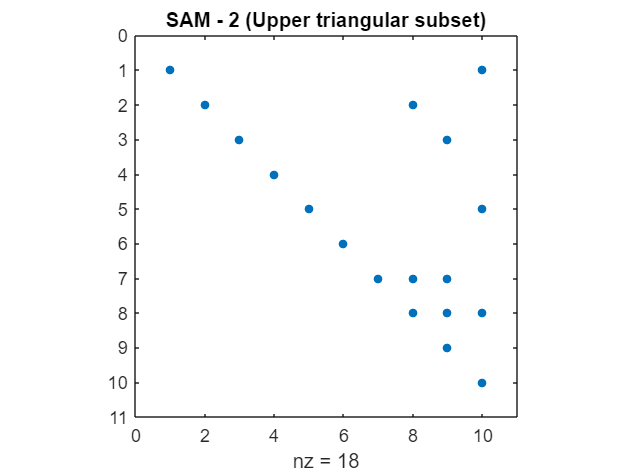

spy(MM);
title("SAM - 2 (Upper triangular subset)");

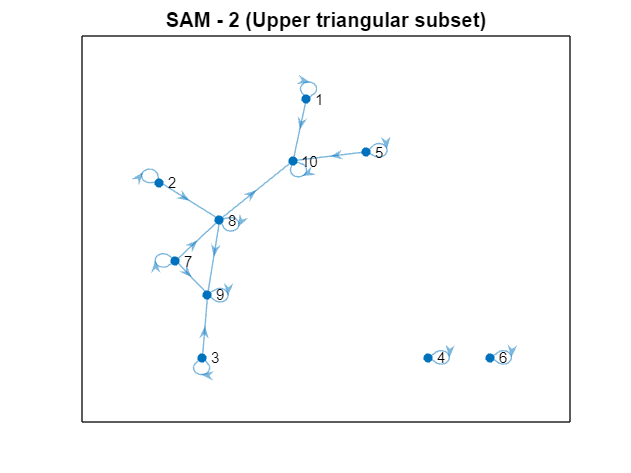

plot(digraph(MM));
title("SAM - 2 (Upper triangular subset)");

% % Compute Exact Map with (Upper Triangular A_0)^2
% N = inv_M_k * (upper_triangular_matrix * upper_triangular_matrix);
% disp(N);
% spy(N);
% title("Computing exact map using A_0^2")
% plot(digraph(N));
% title("G(A_k^-1 * A_0^2)")

% % Extract the lower triangular matrix
% lower_triangular_matrix = tril(M_k);
% 
% % Display the upper triangular matrix
% disp(lower_triangular_matrix);
% spy(lower_triangular_matrix);
% title("Lower triangular subset, A_0")
% plot(digraph(lower_triangular_matrix));
% title("G(A_0)")

% % Compute Exact Map with Lower Triangular A_0
% N = inv_M_k * lower_triangular_matrix;
% disp(N);
% spy(N);
% title("Exact Map - 3 (Lower triangular subset)")
% plot(digraph(N));
% title("G(A_k^-1 * A_0) = G(N)")

% % Extract the tridiagonal band from A_k
% B = spdiags(M_k, [-1 0 1]);
% S = spdiags(B, [-1 0 1], rows, cols);
% disp(S)
% spy(S)
% title("Tridiagonal band subset, A_0")
% plot(digraph(S));
% title("G(A_0)")

% % Compute Exact Map with Tridiagonal A_0
% N = inv_M_k * S;
% disp(N);
% spy(N);
% title("Exact Map - 3 (Tridiagonal subset)")
% plot(digraph(N));
% title("G(A_k^-1 * A_0) = G(N)")